# **Jordan Holbroook**

# **Macroeconometrics (Spring 2022)**

## **Homework 2: Unit Roots**

## Question 1.

This code estimates, using maximum likelihood, the AR(1) process                      $y_t =  + \rho y_{t-1} + e_{t}$ ,

with $e_t \sim NID(0,1).$

## Set the parameters.

There are 50 simulations with 500 observations per simulation. Set $\mu = 0, \rho = 0.5, \rho = 0.1, \rho = 0.95,\rho = 0.99, \rho = 1$ and $\sigma = 1$.

clc
clear

global y T

T = 500;                             % Number of time periods.
mu = 0;                         % Mu.
rho = 0.95;                       % Rho.
sigma = 1;                         % Standard deviation.

sim = 50;                             % Number of simulations.
mle_mat = zeros(sim,3);                                      % MLE matrix.
ols_mat = zeros(sim,3);                                      % OLS matrix.
t_stat_vect = zeros(sim,1);                                 % Vector to capture empirical t-stats

## Maximum Likelihood and OLS Estimation.

for s = 1:sim
    
    % Draw error terms.
    
    u = normrnd(0,sigma,T,1);
    
    % Construct y recursively.
    
    y = zeros(T,1);
    %y(1) = mu/(1-rho) + u(1)/sqrt(1-rho^2);
    %y(1) = 0;
    
    for j = 2:T            
        y(j) = mu + rho*y(j-1) + u(j);            
    end
    
    % MLE.

    Rho_0 = [0 0.95 1];

    options = optimset('Display','off');
    [rho_mle,~,~,~,~,hess] = fminunc('logl_AR',Rho_0,options);
        
    mle_mat(s,:) = rho_mle';
    v_mle = inv(hess);
    
    G = grad_ar1(rho_mle);
    OPG = inv(G'*G);                                       % Outer product of gradients for AR(1).
    
    

    % OLS.
    
    X = [ones(T-1,1) y(1:(T-1))];
    Y = y(2:T);    
    b_ols = (X'*X)\X'*Y;
        
    u_ols  = Y - X*b_ols;
    s2_ols = u_ols'*u_ols/(T-size(X,2));
    
    ols_mat(s,1:2) = b_ols';
    ols_mat(s,3) = sqrt(s2_ols);
    v_ols  = s2_ols./(X'*X);
    
end

t_stats = (mle_mat - Rho_0)./(sqrt(diag(v_mle))');
t_stat_rho = t_stats(:,2);



## Display the results of the last simulation.

The ML estimate and standard error of $\rho$ in the last simulation is:

fprintf(' %0.4f\n(%0.4f)\n(%0.4f)\n',rho_mle(2),sqrt(v_mle(2,2)),sqrt(OPG(2,2)))

 0.9601
(0.0120)
(0.0127)


## Empirical results.

The average and standard deviation (in parenthesis) of $\rho$ estimated using MLE is:

fprintf(' %0.4f\n(%0.4f)\n', mean(mle_mat(:,2)), std(mle_mat(:,2)))

 0.9381
(0.0171)


The empirical T-statistic for $\rho$ is:

fprintf(' %0.4f\n(%0.4f)\n', mean(t_stat_rho))

 -0.9877
(

## Plot the estimated coefficients from all simulations.

bins = 10;

Plot a histogram of $\hat{\rho}$.

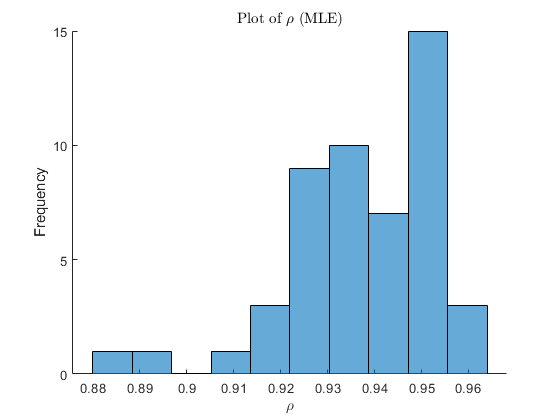

figure(1)
hold on
histogram(mle_mat(:,2),bins)
xlabel('$\rho$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\rho$ (MLE)','interpreter','LaTex')
hold off

Plot a histogram of T-stat.

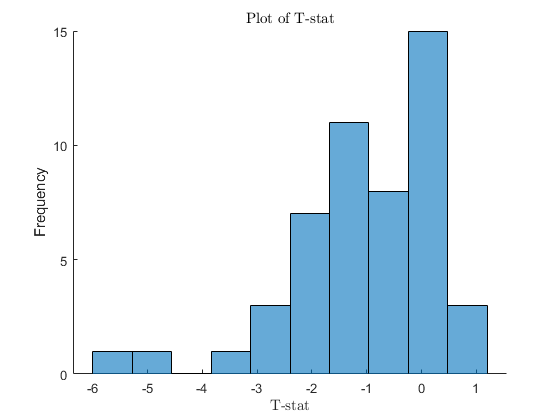

figure(2)
hold on
histogram(t_stat_rho,bins)
xlabel('T-stat','interpreter','LaTex'); ylabel('Frequency')
title('Plot of T-stat','interpreter','LaTex')
hold off

We see that the distribution of our estimate of $\rho$ seems to be biased downward the closer we get to $\rho$=1. That is the closer we get towards a Unit Root process the more bias we have in our estimates. 

## Question 2.

This code estimates, the process                      $y_t = \mu + \rho y_{t-1} + e_{t}$ ,

with $e_t \sim NID(0,1).$

## Set the parameters.

There are 50 simulations with 300 observations per simulation. 

clc
clear
clf

global y T

T = 500;                             % Number of time periods.
mu = 0;                         % Mu.
rho = 1;                       % Rho.
sigma = 1;                         % Standard deviation.

sim = 50;                             % Number of simulations.
ols2_mat = zeros(sim,3);                                      % OLS matrix.
t_stat_vect = zeros(sim,1);                                 % Vector to capture empirical t-stats
coef_vec = [0 0 0 rho];

for s = 1:sim
    
    % Draw error terms.
    
    u = normrnd(0,sigma,T,1);
    
    % Construct y recursively.
    
    y = zeros(T,1);
    for j = 2:T            
        y(j) = mu + rho*y(j-1) + u(j);            
    end
    
    
     %differnece and prepare for OLS
    
    Ldeltay = y(3:T,:) - y(2:T-1,:);
    Ly = y(2:T-1,:);
    deltay = y(2:T-1,:)- y(1:T-2,:);
    t = [3:T]';
    intercept = ones(T-2,1);

    
    % OLS.
    X = [intercept(:,1) t(:,1) Ly deltay];
    Y = Ldeltay;
      
    b_ols = (X'*X)\X'*Y;
        
    u_ols  = Y - X*b_ols;
    s2_ols = u_ols'*u_ols/((T-2)-size(X,2));
    
    ols2_mat(s,1:length(b_ols)) = b_ols';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    %v2_ols  = s2_ols./(X'*X);
    v2_ols  = s2_ols*inv(X'*X);
    
end

t_stats2 = (ols2_mat)./(sqrt(diag(v2_ols))');
t_stat_gamma2 = t_stats2(:,3);



bins = 10;

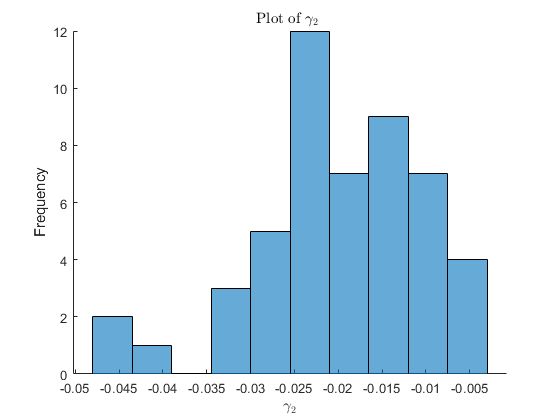


figure(3)
hold on
histogram(ols2_mat(:,3),bins)
xlabel('$\gamma_2$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\gamma_2$ ','interpreter','LaTex')
hold off

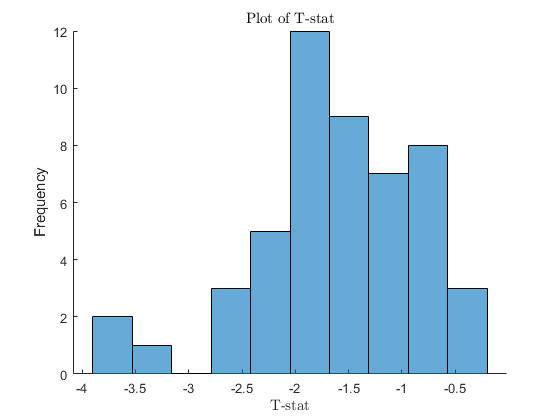

figure(4)
hold on
histogram(t_stat_gamma2,bins)
xlabel('T-stat','interpreter','LaTex'); ylabel('Frequency')
title('Plot of T-stat','interpreter','LaTex')
hold off

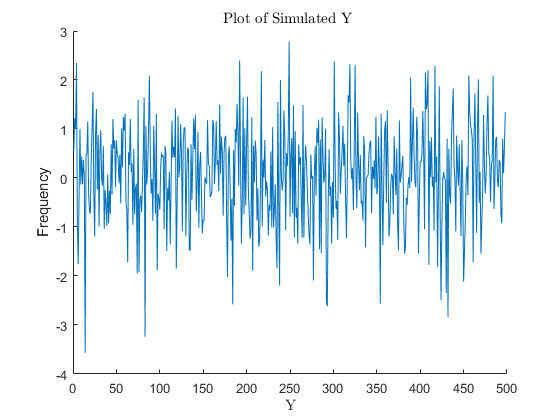

figure(9)
hold on
plot(Y)
xlabel('Y','interpreter','LaTex'); ylabel('Frequency')
title('Plot of Simulated Y ','interpreter','LaTex')
hold off


h = adftest(Y)

h = logical
   1


Here I am a little confused. In the simulation we set $\rho$ =1 thus we were simulating a Unit Root Process. However, the Dickey-Fulller regression test I coded as well as the matlab test package give evidence against the null hypothesis. Thus our dickey-fuller tests indicate that our process does not have a unit root.

## Question 3.

This code estimates, the process                      $y_t = \mu +\delta t +  \rho y_{t-1} + e_{t}$ ,

with $e_t \sim NID(0,1).$

## Set the parameters.

There are 50 simulations with 300 observations per simulation. 

clc
clear


global y T

T = 500;                             % Number of time periods.
mu = 1;                            % Mu.
rho = 0.95;                           % Rho.
sigma = 1;                         % Standard deviation.
delta = 0.5;                         % Delta Time Trend

sim = 50;                             % Number of simulations.
ols3_mat = zeros(sim,3);                                      % OLS matrix.                               
coef_vec = [0 mu delta rho];

for s = 1:sim
    
    % Draw error terms.
    
    u = normrnd(0,sigma,T,1);
    
    % Construct y recursively.
    
    y = zeros(T,1);
    for j = 2:T            
        y(j) = mu + delta*(j-1) + rho*y(j-1) + u(j);            
    end
    
    
    %differnece and prepare for OLS
    %Ldeltay = y(1:T-1,:) - y(2:T,:);
    Ldeltay = y(3:T,:) - y(2:T-1,:);
    %Ldeltay = diff(y);
    %Ldeltay=Ldeltay(1:end-1);
    
    
    Ly = y(2:T-1,:);
    
    
    deltay = y(2:T-1,:)- y(1:T-2,:);
    %deltay = diff(Ly);
    %deltay=deltay(1:end-1);
    t = [3:T]';
    intercept = ones(T-2,1);

    
    % OLS.
    
    X = [intercept(:,1) t(:,1) Ly deltay];
    Y = Ldeltay;    
    b_ols = (X'*X)\X'*Y;
        
    u_ols  = Y - X*b_ols;
    s2_ols = (u_ols'*u_ols)/((T-2)-size(X,2));
    
    ols3_mat(s,1:length(b_ols)) = b_ols';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    
    %v3_ols  = s2_ols./(X'*X);
    v3_ols  = s2_ols*inv(X'*X);
    
end

%t_stat_1 = ols3_mat(:,3)./(sqrt(v3_ols1(3,3))')
t_stats3 = (ols3_mat)./(sqrt(diag(v3_ols))');
t_stat_gamma2_3 = t_stats3(:,3);


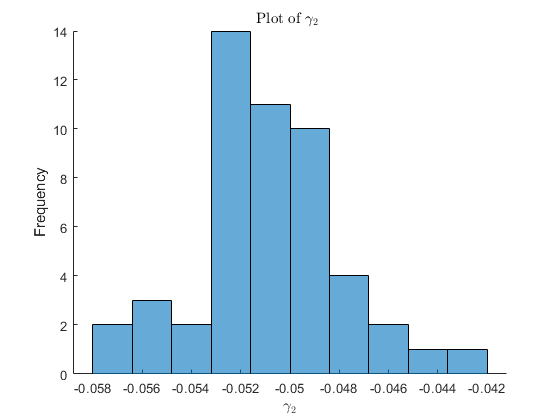

bins = 10;

figure(5)
hold on
histogram(ols3_mat(:,3),bins)
xlabel('$\gamma_2$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\gamma_2$ ','interpreter','LaTex')
hold off

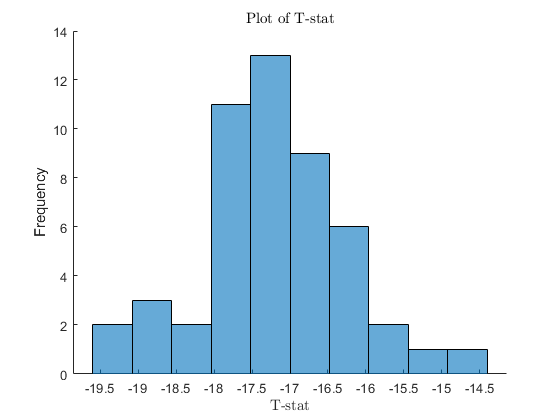



figure(6)
hold on
histogram(t_stat_gamma2_3,bins)
xlabel('T-stat','interpreter','LaTex'); ylabel('Frequency')
title('Plot of T-stat','interpreter','LaTex')
hold off

Here we see that even when we are close to a Unit Root Process with $\rho$=0.95 our dickey-fuller test has a lot of power to reject the null hypothesis. The distribution of t-stats all are well above our critical value range.

## Question 4.

This code estimates, the processes                      $y_t =   \rho y_{t-1} + e_{t}$ , 

                                                                               
$$x_t = \rho x_{t-1} + u_t$$


with $u_t  , e_t \sim NID(0,1).$

## Set the parameters.

There are 50 simulations with 300 observations per simulation. 

clc
clear

global y T

T = 300;                             % Number of time periods.
mu = 1;                            % Mu.
rho = 1;                           % Rho.
sigma = 1;                         % Standard deviation.
delta = 0.5;                         % Delta Time Trend

sim = 50;                             % Number of simulations.
ols4_mat = zeros(sim,2);                                      % OLS matrix.                               
coef_vec = [0 0];


for s = 1:sim
    
    % Draw error terms.
    
    e = normrnd(0,1,T,1); %innovations for y
    
    u = normrnd(0,1,T,1); %innovations for x
    
    y = zeros(T,1);
    x = zeros(T,1);
    for i=2:T
        y(i,:) = y(i-1)*rho + e(i,:);
        x(i,:) = x(i-1)*rho + u(i,:);
    end
    
    
    % OLS.
    
    X = [ones(T-1,1) x(1:T-1)];
    Y = y(1:T-1);    
    b_ols = (X'*X)\X'*Y;
        
    u_ols  = Y - X*b_ols;
    s2_ols = u_ols'*u_ols/(T-size(X,2));
    
    ols4_mat(s,1:2) = b_ols';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    v4_ols  = s2_ols./(X'*X);
    
end

t_stats4 = (ols4_mat)./(sqrt(diag(v4_ols))');
t_stat_alpha = t_stats4(:,2);



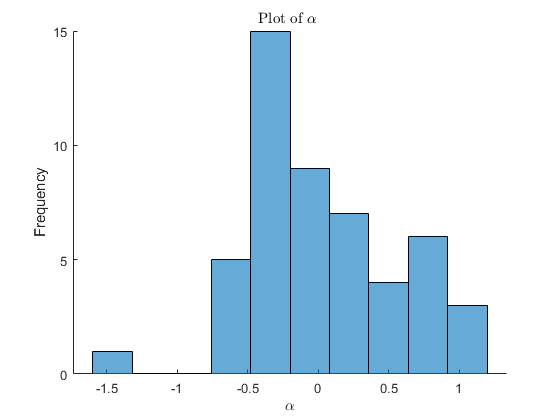


bins = 10;

figure(7)
hold on
histogram(ols4_mat(:,2),bins)
xlabel('$\alpha$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\alpha$ ','interpreter','LaTex')
hold off

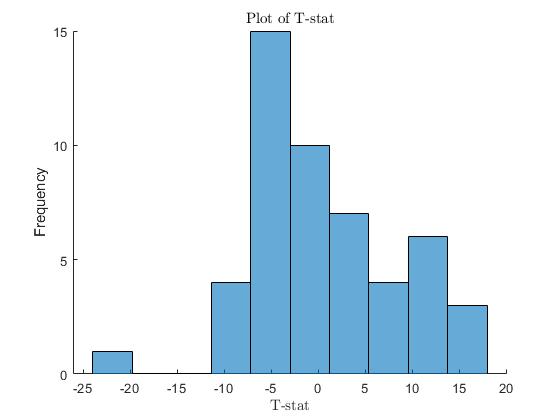


figure(8)
hold on
histogram(t_stat_alpha,bins)
xlabel('T-stat','interpreter','LaTex'); ylabel('Frequency')
title('Plot of T-stat','interpreter','LaTex')
hold off

The mean and median values from the simulated $\hat{\alpha}$ distribution.

fprintf(' %0.4f\n %0.4f\n', mean(ols4_mat(:,2)), median(ols4_mat(:,2)))

 0.0463
 -0.0816


With $\rho$ =1 our OLS estimate is biased, but still predicts $\hat{\alpha}$  a portion of the time. Our t-statistics are extremely errogenous however, reporting very strong evidence of a significant statistical relationship between the two processes. Even with $\rho$ = 0.95 our t-statistics reject the null more than 5% of the time. We reject the null around 10% or 15% of the time. Thus, the closer we are to a Unit Root process the easier it is to believe there exists a statistically significant relationship when there is actually no relationship.